clear; close; clc;
load('DiagnosisTable.mat')
diagnosesicd.subject_id

ans =     10035185
    10035185
    10035185
    10035185
    10035185
    10035185
    10035185
    10035185
    10035185
    10035185


diagnosesicd.hadm_id

ans =     22580999
    22580999
    22580999
    22580999
    22580999
    22580999
    22580999
    22580999
    22580999
    22580999


diagnosesicd.icd_code

ans =         4139
         NaN
       41401
        3899
         NaN
       25002
       71696
         NaN
        2724
         NaN



inputData = readcell("diagnoses_icd.csv") % Read Data

inputData = 4507×5 cell array
    {'subject_id'}    {'hadm_id' }    {'seq_num'}    {'icd_code'}    {'icd_version'}
    {[  10035185]}    {[22580999]}    {[      3]}    {[    4139]}    {[          9]}
    {[  10035185]}    {[22580999]}    {[     10]}    {'V707'    }    {[          9]}
    {[  10035185]}    {[22580999]}    {[      1]}    {[   41401]}    {[          9]}
    {[  10035185]}    {[22580999]}    {[      9]}    {[    3899]}    {[          9]}
    {[  10035185]}    {[22580999]}    {[     11]}    {'V8532'   }    {[          9]}
    {[  10035185]}    {[22580999]}    {[      2]}    {[   25002]}    {[          9]}
    {[  10035185]}    {[22580999]}    {[      7]}    {[   71696]}    {[          9]}
    {[  10035185]}    {[22580999]}    {[      8]}    {'V1083'   }    {[          9]}
    {[  10035185]}    {[22580999]}    {[      4]}    {[    2724]}    {[          9]}
    {[  10035185]}    {[22580999]}    {[      6]}    {'V5867'   }    {[          9]}
    {[  10035185]}    {[22580999]} 


% remove the things we dont need
inputData(:,5) = [];
inputData(:,3) = [];

% convert icd codes to strings
inputData(:,3) = arrayfun( @(x) {string(x)}, inputData(:,3));

icd_codes = arrayfun( @(x) string(x), inputData(2:end,3))

icd_codes = 4506×1 string array
    "4139"
    "V707"
    "41401"
    "3899"
    "V8532"
    "25002"
    "71696"
    "V1083"
    "2724"
    "V5867"
    "27800"
    "4829"
    "99592"
    "2768"
    "388"
    "78791"
    "5601"
    "2875"
    "60001"
    "79092"
    "5110"
    "2859"
    "5849"
    "78820"
    "4240"
    "V4589"
    "5121"
    "7873"
    "99832"
    "33812"


icd_bitSet_mapping = unique(icd_codes)

icd_bitSet_mapping = 1470×1 string array
    "1120"
    "1121"
    "1122"
    "1123"
    "11289"
    "1173"
    "1179"
    "1369"
    "1419"
    "1505"
    "1540"
    "1541"
    "1543"
    "1548"
    "1551"
    "1560"
    "1571"
    "1622"
    "1625"
    "1629"
    "1741"
    "1759"
    "1962"
    "1968"
    "1970"
    "1971"
    "1977"
    "1978"
    "1980"
    "1983"


## one hot encoding of diagnosies

hotData = zeros([length(icd_codes),length(icd_bitSet_mapping)],"logical");

% find(icd_bitSet_mapping == icd_codes(1)) %maps value to index

for i = 1:length(icd_codes)
    hotData(i,:) = (icd_bitSet_mapping == icd_codes(i))';
end
%one line equivalent
% hotData = cell2mat(arrayfun(@(x) (icd_bitSet_mapping == x)', icd_codes,UniformOutput=false));


## now we will find patient visits

%import subject and admitance ids
subject_ids = arrayfun( @(x) uint32(str2double(string(x))), inputData(2:end,1));

hadm_ids = arrayfun( @(x) uint32(str2double(string(x))), inputData(2:end,2));

%find the unique visits
visitIds = [subject_ids,hadm_ids];
[uniqueVists, first_unique_vist_indices, uniqueVisits_index] = unique(visitIds,"rows","first");



## create the 1 hot diagnosis set associated to each unique visit

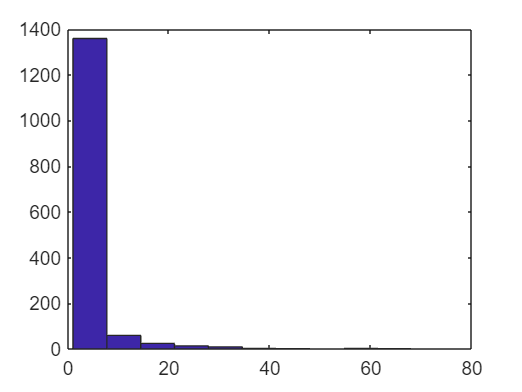

uniqueHotDiagnosies = zeros([size(uniqueVists,1),size(hotData,2)]);

for i = 1:length(uniqueVists)
    matchingVisits = visitIds(:,:) == uniqueVists(i,:); % find a specific visit
    Visit_indices = find(bitand(matchingVisits(:,1),matchingVisits(:,2))); % its associated indices
    
    %take bitwize or of all the diagnosis for each visit
    HotDiagnoises = zeros([1,size(hotData,2)]);
    for j = 1:length(Visit_indices)
        visitIndex = Visit_indices(j,:);
        HotDiagnoises = bitor(HotDiagnoises,hotData(visitIndex,:));
    end
    %TODO assign
    uniqueHotDiagnosies(i,:) = HotDiagnoises;
end

hist(sum(uniqueHotDiagnosies))

## create pairs of visits

uniqueVists

uniqueVists = 275×2 uint32 matrix
   10000032   22595853
   10000032   22841357
   10000032   25742920
   10000032   29079034
   10001217   24597018
   10001217   27703517
   10001725   25563031
   10002428   20321825
   10002428   23473524
   10002428   25797028



uniquePatients = unique(uniqueVists(:,1)) % find each unquie patient

uniquePatients = 100×1 uint32 column vector
   10000032
   10001217
   10001725
   10002428
   10002495
   10002930
   10003046
   10003400
   10004235
   10004422



%for each unque patient if they have more than one visit get the pairs of
%indicies of the visits
admitance_index_pairs = [];

for i = 1:length(uniquePatients)
    admitance_indexes = find(uniqueVists(:,1) == uniquePatients(i)); % get the visits
    
    if(length(admitance_indexes) > 1) % this patient has visted multiple times thus we can use them in our model
        for j = 1:(length(admitance_indexes)-1)
            admitance_index_pair = [admitance_indexes(j),admitance_indexes(j+1)];
            admitance_index_pairs = [admitance_index_pairs;admitance_index_pair]; % this is terrible programming but idk if i can be low level enought to fix in matlab
        end
    end
end


## Asseble the data matrices

% each coloumn of the first data matix should be a diagonosis 1 hot bitset
% assosiated with the first pair of a pair of visits

% we will first assable the data sideways with the snapshots (patients) as
% rows then we will rotate at the end
firstVisitData = zeros(size(admitance_index_pairs,1),size(hotData,2));
secondVisitData = zeros(size(admitance_index_pairs,1),size(hotData,2));

for i = 1:length(admitance_index_pairs)
    firstVisitData(i,:) = uniqueHotDiagnosies(admitance_index_pairs(i,1),:);
    secondVisitData(i,:) = uniqueHotDiagnosies(admitance_index_pairs(i,2),:);
end

firstVisitData = firstVisitData';
secondVisitData = secondVisitData';

sum(sum(firstVisitData))

ans = 2944

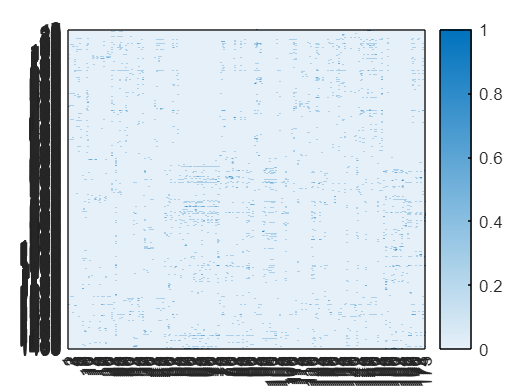

heatmap(firstVisitData); grid off;

sum(sum(secondVisitData))

ans = 2945

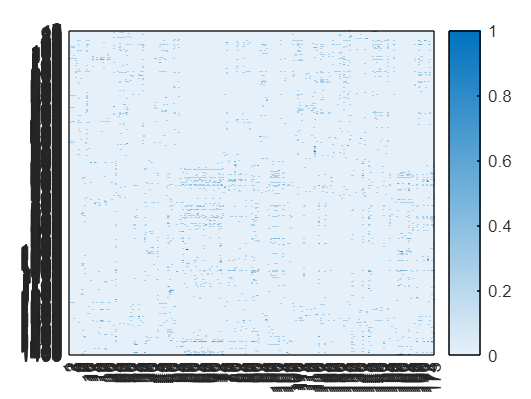

heatmap(secondVisitData); grid off;


save("Repeated_Visit_Snapshot_Data","firstVisitData","secondVisitData");